# Diseño de un sistema regulador con observador de estados de orden mínimo

% Ejemplo seccion 10-6 Texto Ogata. Diseño de sistemas reguladores con
% observadores
clear
close all
A = [0 1 0;0 0 1;0 -24 -10]

A =      0     1     0
     0     0     1
     0   -24   -10


B = [0;10;-80]

B =      0
    10
   -80


C = [1 0 0]

C =      1     0     0


J = [-1+1i*2 -1-1i*2 -5]

J =   -1.0000 + 2.0000i  -1.0000 - 2.0000i  -5.0000 + 0.0000i


sys_ol=ss(A,B,C,0);

## Prueba de controlabilidad

sys_ord=order(sys_ol)

sys_ord = 3

rank_sys=rank(ctrb(A,B))

rank_sys = 3

det(ctrb(A,B))

ans = -16000

## Prueba de observabilidad

rank_sys=rank(obsv(sys_ol))

rank_sys = 3

det_sys=det(obsv(sys_ol))

det_sys = 1

## Obtención de la matriz de realimentación de los estados K

K = acker(A,B,J)

K =     1.2500    1.2500    0.1938


K=place(A,B,J)

K =     1.2500    1.2500    0.1938


% Obtaining the observer gain matrix Ke
% Ver ecuaciones 10-81 y 10-82
Aaa = 0

Aaa = 0

Aab = [1 0]

Aab =      1     0


Aba = [0;0]

Aba =      0
     0


Abb = [0 1;-24 -10]

Abb =      0     1
   -24   -10


Ba = 0

Ba = 0

Bb = [10;-80]

Bb =     10
   -80


L = [-10 -10]

L =    -10   -10


## Obtención de la matriz de ganancias Ke para el observador

Ke = acker(Abb',Aab',L)'

Ke =     10
   -24


%Ke=place(Abb',Aab',L)

## Obtencion de la función de transferencia del controlador-observador

Ka=K(1);
Kb=K(2:3);
Ahat = Abb - Ke*Aab;
Bhat = Ahat*Ke + Aba - Ke*Aaa;
Fhat = Bb - Ke*Ba;
% Matrices que definen las ecuaciones 10-106 y 10-107
Atilde = Ahat - Fhat*Kb;
Btilde = Bhat - Fhat*(Ka + Kb*Ke);
Ctilde = -Kb;
Dtilde = -(Ka + Kb*Ke);
% Ecuacion 10-109

### Con la función ss2tf de MATLAB

[num,den] = ss2tf(Atilde, Btilde, -Ctilde, -Dtilde)

num =     9.1000   73.5000  125.0000


den =     1.0000   17.0000  -30.0000


Gcobs1=tf(num,den)

Gcobs1 =
 
  9.1 s^2 + 73.5 s + 125
  ----------------------
     s^2 + 17 s - 30
 
Continuous-time transfer function.
Model Properties


### En forma simbólica

syms s
% Ecuacion 10-108
sys1=-(Ctilde*inv(s*eye(size(Atilde,1))-Atilde)*Btilde+Dtilde);
Gcobss=simplify(sys1)

$$Gcobss = \frac{91\,s^{2}+735\,s+1250}{10\,\left(s^{2}+17\,s-30\right)}$$

pole(Gcobs1)

ans =   -18.6119
    1.6119


#### Observación: el sistema es inestable en lazo abierto

## Cálculo de la ecuación característica 

### Mediante la funcion ss2tf de MATLAB

[num1,den1] = ss2tf(A-B*K,eye(3),eye(3),eye(3),1);
[num2,den2] = ss2tf(Abb-Ke*Aab,eye(2),eye(2),eye(2),1);
charact_eq = conv(den1,den2)

charact_eq = 1.0e+03 *

    0.0010    0.0270    0.2550    1.0250    2.0000    2.5000


roots(charact_eq)

ans =  -10.0000 + 0.0000i
 -10.0000 - 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


### En forma simbólica

syms s
charact_eqs=det(s*eye(size(A,1))-A+B*K)*det(s*eye(size(Abb,1))-Abb+Ke*Aab)

$$charact\_eqs = {\left(s+10\right)}^{2}\,\left(s^{3}+7\,s^{2}+15\,s+25\right)$$

roots(conv([1 20 100],[1 7 15 25]))

ans =  -10.0000 + 0.0000i
 -10.0000 - 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


# Observación: el sistema es estable en lazo cerrado

## Segunda prueba:

### Modificando  los polos deseados para el observador de orden mínimo 

L = [-4.5 -4.5]

L =    -4.5000   -4.5000


Ke = acker(Abb',Aab',L)'

Ke =    -1.0000
    6.2500


Ahat = Abb - Ke*Aab;
Bhat = Ahat*Ke + Aba - Ke*Aaa;
Fhat = Bb - Ke*Ba;
% Matrices que definen las ecuaciones 10-106 y 10-107
Atilde = Ahat - Fhat*Kb;
Btilde = Bhat - Fhat*(Ka + Kb*Ke);
Ctilde = -Kb;
Dtilde = -(Ka + Kb*Ke);

## Obtencion de la función de transferencia del controlador-observador

[num,den] = ss2tf(Atilde, Btilde, -Ctilde, -Dtilde)

num =     1.2109   11.2125   25.3125


den =     1.0000    6.0000    2.1406


Gcobs2=tf(num,den)

Gcobs2 =
 
  1.211 s^2 + 11.21 s + 25.31
  ---------------------------
       s^2 + 6 s + 2.141
 
Continuous-time transfer function.
Model Properties


pole(Gcobs2)

ans =    -5.6190
   -0.3810


## Cálculo de la ecuación característica 

### Mediante la funcion ss2tf de MATLAB

[num1,den1] = ss2tf(A-B*K,eye(3),eye(3),eye(3),1);
[num2,den2] = ss2tf(Abb-Ke*Aab,eye(2),eye(2),eye(2),1);
charact_eq = conv(den1,den2)

charact_eq =     1.0000   16.0000   98.2500  301.7500  528.7500  506.2500


roots(charact_eq)

ans =   -5.0000 + 0.0000i
  -4.5000 + 0.0000i
  -4.5000 + 0.0000i
  -1.0000 + 2.0000i
  -1.0000 - 2.0000i


## Obtención de la respuesta del sistema a condiciones iniciales

% Ecuaciones 10-110 y 10-111 (10-94)
AA = [A-B*K B*Kb; zeros(2,3) Abb-Ke*Aab]

AA =          0    1.0000         0         0         0
  -12.5000  -12.5000   -0.9375   12.5000    1.9375
  100.0000   76.0000    5.5000 -100.0000  -15.5000
         0         0         0    1.0000    1.0000
         0         0         0  -30.2500  -10.0000


sys = ss(AA,eye(5),eye(5),eye(5));
t = 0:0.01:8;
x0=[1;0;0;1;0]   % vector de condiciones iniciales

x0 =      1
     0
     0
     1
     0


x = initial(sys,x0,t)

x =     1.0000         0         0    1.0000         0
    1.0000   -0.0022    0.0180    1.0086   -0.2892
    0.9999   -0.0087    0.0702    1.0145   -0.5529
    0.9998   -0.0191    0.1540    1.0179   -0.7929
    0.9995   -0.0329    0.2670    1.0190   -1.0107
    0.9991   -0.0500    0.4069    1.0181   -1.2078
    0.9985   -0.0700    0.5715    1.0153   -1.3855
    0.9977   -0.0926    0.7587    1.0108   -1.5453
    0.9967   -0.1176    0.9665    1.0047   -1.6884
    0.9954   -0.1447    1.1930    0.9971   -1.8158


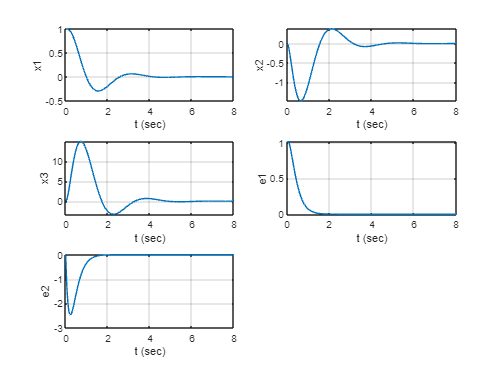

x1 = [1 0 0 0 0]*x';
x2 = [0 1 0 0 0]*x';
x3 = [0 0 1 0 0]*x';
e1 = [0 0 0 1 0]*x';
e2 = [0 0 0 0 1]*x';
figure(1000)
subplot(3,2,1); plot(t,x1); grid
xlabel ('t (sec)'); ylabel('x1')
subplot(3,2,2); plot(t,x2); grid
xlabel ('t (sec)'); ylabel('x2')
subplot(3,2,3); plot(t,x3); grid
xlabel ('t (sec)'); ylabel('x3')
subplot(3,2,4); plot(t,e1); grid
xlabel('t (sec)'); ylabel('e1')
subplot(3,2,5); plot(t,e2); grid
xlabel('t (sec)'); ylabel('e2')

## Diagramas del Bode del sistema regulador diseñado

numol=10*[1 2];
denol=conv([1 4 0],[1 6]);
Gsol=tf(numol,denol)

Gsol =
 
       10 s + 20
  -------------------
  s^3 + 10 s^2 + 24 s
 
Continuous-time transfer function.
Model Properties


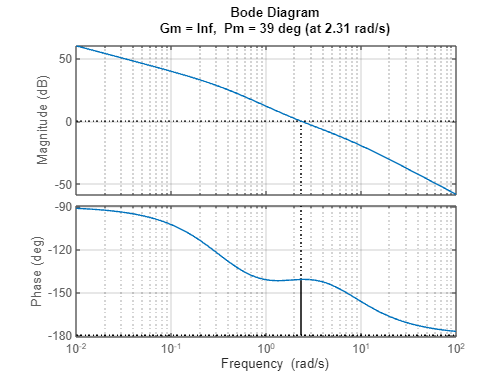

figure(1)
margin(Gsol*Gcobs2)
grid

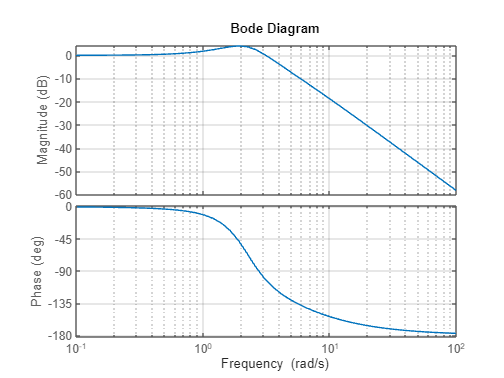

figure(2)
bode(feedback(Gsol*Gcobs2,1))
grid

## Root Locus del sistema regulador con polos del observador en s=-10 y s=-10

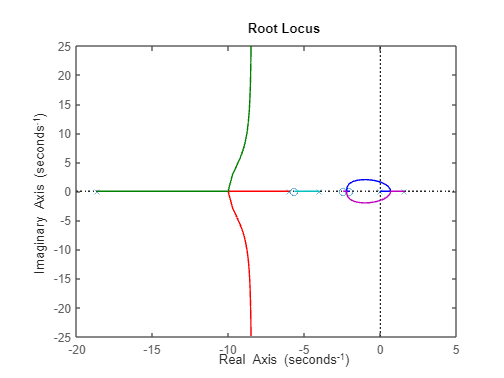

figure(3)
rlocus(Gsol*Gcobs1)

Gsol*Gcobs1

ans =
 
      91 s^3 + 917 s^2 + 2720 s + 2500
  ----------------------------------------
  s^5 + 27 s^4 + 164 s^3 + 108 s^2 - 720 s
 
Continuous-time transfer function.
Model Properties


## Root Locus del sistema regulador con polos del observador en s=-4.5 y s=-4.5

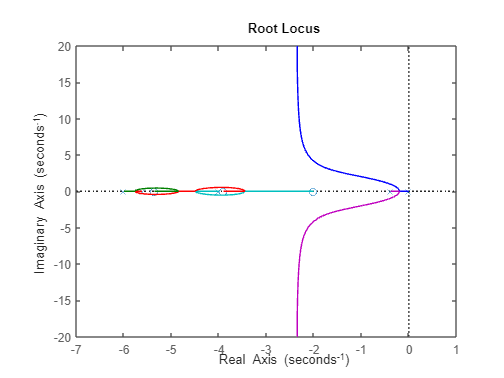

figure(4)
rlocus(Gsol*Gcobs2)

Gsol*Gcobs2

ans =
 
     12.11 s^3 + 136.3 s^2 + 477.4 s + 506.3
  ----------------------------------------------
  s^5 + 16 s^4 + 86.14 s^3 + 165.4 s^2 + 51.37 s
 
Continuous-time transfer function.
Model Properties
